A live script to examine the Yeast8 model and see why some simulations were getting yields where the biomass weighs more than the input cellulose.

**Part 1: Unmodified Yeast 8 eating a fixed amount of glc.**

if ~exist('model_default','var')
    model_default = load('C:\sync\biomes\models\yeastGEM_8.3.2.mat');
    model_default = model_default.model;
end
model = model_default;

model.lb(stridx('D-glucose exchange',model.rxnNames)) = -10;   

%% Change metabolite names to be consistent with exchanges and enzyme production requirements
model.mets{311} = 'nh4[e]';
model.mets{345} = 'co2[e]';
model.mets{431} = 'glc-D[e]';
model.mets{512} = 'ergst[e]';
model.mets{520} = 'etoh[e]';
model.mets{572} = 'gthox[e]';
model.mets{603} = 'h[e]';
model.mets{612} = 'h2o[e]';
model.mets{720} = 'fe2[e]';
model.mets{1005} = 'o2[e]';
model.mets{1037} = 'pi[e]';
model.mets{1055} = 'k[e]';
model.mets{1135} = 'so4[e]';
model.mets{1215} = 'zymst[e]';

v = getOptVars();
v.initglc = 10;
v.initfe2 = 1000;
v.initgthox = 1000;
v.initialpop = 1;

layout = createLayout();
layout.params.maxSpaceBiomass = 100000;
layout = addModel(layout,model);
layout = setInitialPop(layout,'1x1',v.initialpop);

layout = setMedia(layout,'o2[e]',v.initO2);
layout = setMedia(layout,'h2o[e]',v.initH2O);
layout = setMedia(layout,'co2[e]',v.initCO2);
layout = setMedia(layout,'pi[e]',v.initPi);
layout = setMedia(layout,'so4[e]',v.initSO4);
layout = setMedia(layout,'nh4[e]',v.initNH4);
layout = setMedia(layout,'k[e]',v.initK);
layout = setMedia(layout,'glc-D[e]',v.initglc);

layout = setMedia(layout,'fe2[e]',v.initfe2);
% layout = setMedia(layout,'gthox[e]',v.initgthox);
% 
% layout = setMedia(layout,'zymst[e]',100);
% layout = setMedia(layout,'ergst[e]',100);

layout.params.writeBiomassLog = true;
layout.params.writeMediaLog = true;
layout.params.maxCycles = 500;
curdir = pwd;
cd 'C:\sync\biomes\cellulose\optima\temp';
runComets(layout);

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


biomass = parseBiomassLog(layout.params.biomassLogName);
media = parseMediaLog(layout.params.mediaLogName);

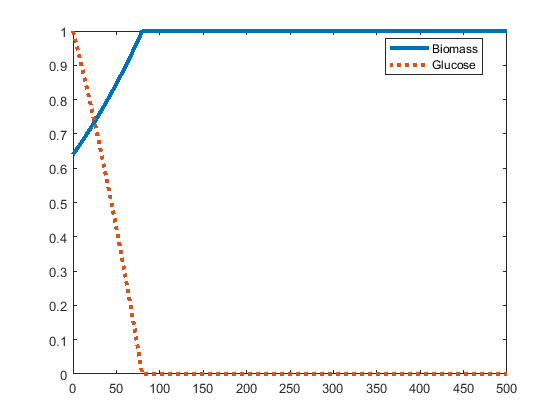

%Confirm growth happened and all glucose is consumed
glc = media(strcmp(media.metname,'glc-D[e]'),:);
y.glc = glc.amt/max(glc.amt);
y.biomass = biomass.biomass/max(biomass.biomass);
plot(biomass.t,y.biomass,'-',glc.t,y.glc,':','linewidth',3);
legend({'Biomass' 'Glucose'},'location','best');

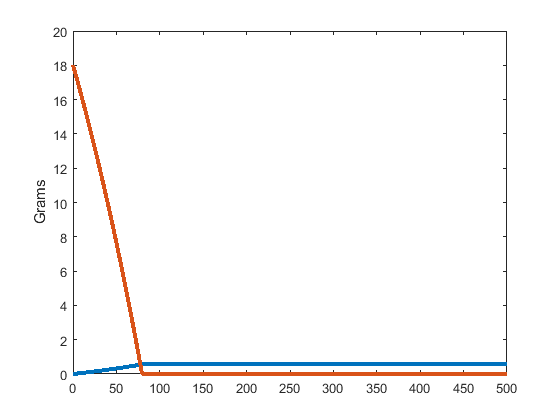

mass_glc = (v.initglc / 1000) * 180.156; %grams
biodelta = biomass.biomass - v.initialpop;

plot(biomass.t,biodelta,glc.t,mass_glc * glc.amt,'linewidth',3)
ylabel('Grams');

**Part 2: enzyme producer eating glucose**

if ~exist('model_default','var')
    model_default = load('C:\sync\biomes\models\yeastGEM_8.3.2.mat');
    model_default = model_default.model;
end
model = model_default;

model.lb(stridx('D-glucose exchange',model.rxnNames)) = -10;   

v = getOptVars();
v.initglc = 10;
v.initfe2 = 1000;
v.initgthox = 1000;
v.initialpop = 1;
v.alpha = exp(-7);
model = prepareYeastGEMModel(model,v);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR


layout = createLayout();
layout.params.maxSpaceBiomass = 100000;
layout = addModel(layout,model);
layout = setInitialPop(layout,'1x1',v.initialpop);

layout = setMedia(layout,'o2[e]',v.initO2);
layout = setMedia(layout,'h2o[e]',v.initH2O);
layout = setMedia(layout,'co2[e]',v.initCO2);
layout = setMedia(layout,'pi[e]',v.initPi);
layout = setMedia(layout,'so4[e]',v.initSO4);
layout = setMedia(layout,'nh4[e]',v.initNH4);
layout = setMedia(layout,'k[e]',v.initK);
layout = setMedia(layout,'glc-D[e]',v.initglc);

layout = setMedia(layout,'fe2[e]',v.initfe2);
% layout = setMedia(layout,'gthox[e]',v.initgthox);

% layout = setMedia(layout,'zymst[e]',100);
% layout = setMedia(layout,'ergst[e]',100);

layout.params.writeBiomassLog = true;
layout.params.writeMediaLog = true;
layout.params.maxCycles = 500;

curdir = pwd;
cd 'C:\sync\biomes\cellulose\optima\temp';
runComets(layout);

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


biomass = parseBiomassLog(layout.params.biomassLogName);
media = parseMediaLog(layout.params.mediaLogName);

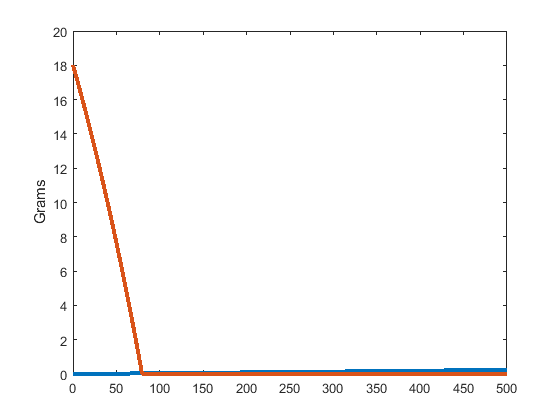

mass_glc = (v.initglc / 1000) * 180.156; %grams
biodelta = biomass.biomass - v.initialpop;

plot(biomass.t,biodelta,glc.t,mass_glc * glc.amt,'linewidth',3)
ylabel('Grams');

**Part 3: Examining data from master pipeline Part3**

datadir = 'C:\sync\biomes\cellulose\optima\clean_version\data';
if ~exist('dat3','var')
        load([datadir '\dat3.mat']);
end
g_avicel_per_mol =  (180.156 - 17) * v.glcpercellulose;
dat3.yield = (dat3.biomass_max - cellfun(@(x) x(1),dat3.biomass))  ./ (dat3.initcel * g_avicel_per_mol / 1000);
dat3.g_cellulose = dat3.initcel * g_avicel_per_mol / 1000;
dat3_partial = dat3(mod(log(dat3.alpha),1) == 0,:);
initcelamts = unique(dat3_partial.initcel);
g_avicel = (initcelamts) * (180.156 - 17) * v.glcpercellulose / 1000;
ic = initcelamts(end)

ic = 0.0999

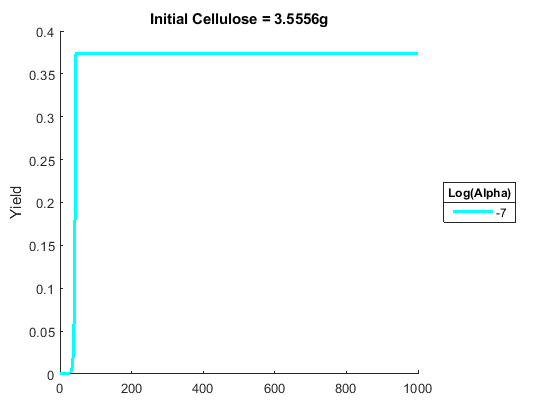

ydat = dat3_partial(dat3_partial.initcel == ic,:);

figure();
hold on;
[nrows,~] = size(ydat);
colors = lines(nrows);
colors = jet(nrows);
for i = 1:nrows
    plot(ydat.t{i},ydat.biomass{i}/ydat.g_cellulose(i),'color',colors(i,:),'linewidth',2);
end
leg = legend(num2str(log(ydat.alpha)),'location','eastoutside');
title(leg,'Log(Alpha)')
ylabel('Yield')
hold off;
title(['Initial Cellulose = ' num2str(g_avicel(length(initcelamts))) 'g']);

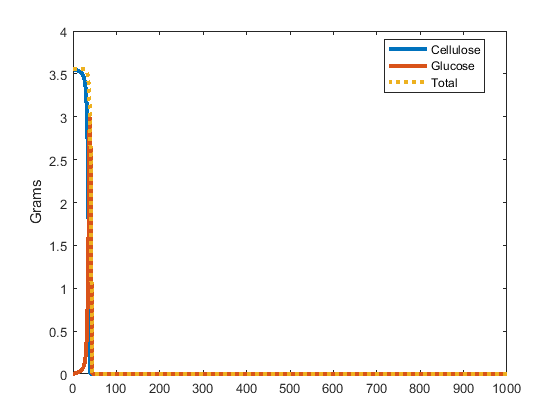

row = ydat(ydat.alpha == exp(-7),:);
%plot(row.t{1},row.cellulose_amt{1},row.t{1},row.glc_amt{1},'linewidth',3);
g_cel = row.cellulose_amt{1} * g_avicel_per_mol / 1000;
g_glc = row.glc_amt{1} * 180.156;
g_glc_norm = row.glc_amt{1} * (180.156 - 17) / 1000; 
g_all_sugar = g_cel + g_glc_norm;
t = row.t{1};
plot(t,g_cel,'-',t,g_glc_norm,'-',t,g_all_sugar,':','linewidth',3);
legend({'Cellulose', 'Glucose', 'Total'},'location','best');
ylabel('Grams')